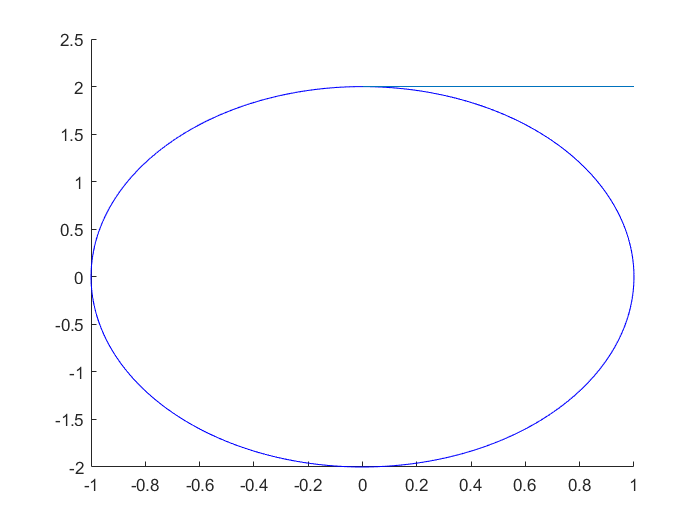

%Задание номер 2. (которое было не сделано)
cla()
t0 = 8*pi/2;
x0 = sin(t0);
y0 = 2*cos(t0);
t = 0:0.05:9*pi;
x = sin(t);
y = 2*cos(t);
x_d = cos(t0);
y_d = -2*sin(t0);
hold on;
plot(x,y,"b")
line([x0, x0+x_d], [y0, y0+y_d]);
hold off;

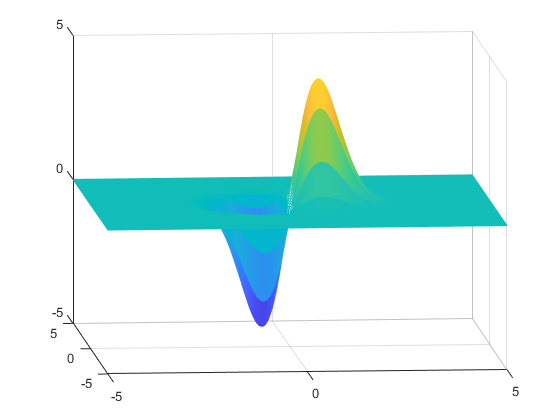

% Домашнее задание. 109 группа. Кабанов Степан.
% №1
[x, y] = meshgrid(-5:0.5:5, -5:0.5:5);
z = 5.*x + 9.*y - 8;
subplot(1,1,1)

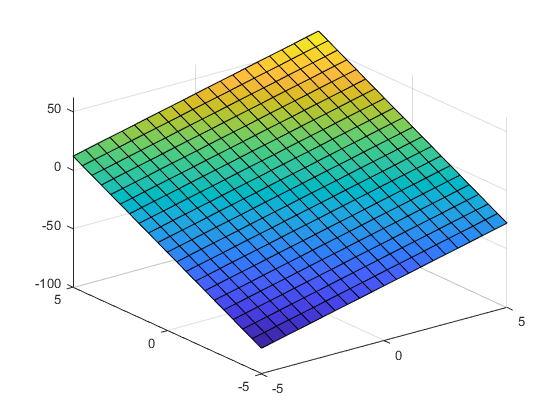

surf(x,y,z)

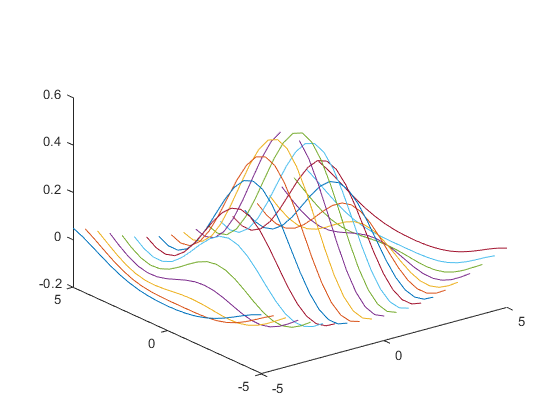

% 2 a, b
a = 0.5;
[x,y] = meshgrid(-5:0.5:5, -5:0.5:5);
z = a.*sin(sqrt(x.^2 + y.^2)) ./ sqrt(x.^2 + y.^2);
plot3(x,y,z)


z = -x.*sin(x) - y.*cos(y)

z =     6.2129    5.8172    4.4455    2.6461    0.9950   -0.0779   -0.4003   -0.0779    0.5768    1.1786    1.4183    1.1786    0.5768   -0.0779   -0.4003   -0.0779    0.9950    2.6461    4.4455    5.8172    6.2129
    3.8460    3.4503    2.0786    0.2792   -1.3719   -2.4448   -2.7672   -2.4448   -1.7901   -1.1883   -0.9486   -1.1883   -1.7901   -2.4448   -2.7672   -2.4448   -1.3719    0.2792    2.0786    3.4503    3.8460
    2.1800    1.7843    0.4126   -1.3868   -3.0379   -4.1108   -4.4332   -4.1108   -3.4560   -2.8543   -2.6146   -2.8543   -3.4560   -4.1108   -4.4332   -4.1108   -3.0379   -1.3868    0.4126    1.7843    2.1800
    1.5170    1.1213   -0.2504   -2.0499   -3.7010   -4.7738   -5.0962   -4.7738   -4.1191   -3.5173   -3.2776   -3.5173   -4.1191   -4.7738   -5.0962   -4.7738   -3.7010   -2.0499   -0.2504    1.1213    1.5170
    1.8246    1.4289    0.0572   -1.7422   -3.3933   -4.4662   -4.7886   -4.4662   -3.8114   -3.2097   -2.9700   -3.2097   -3.8114   -4.4662   -4.7886  

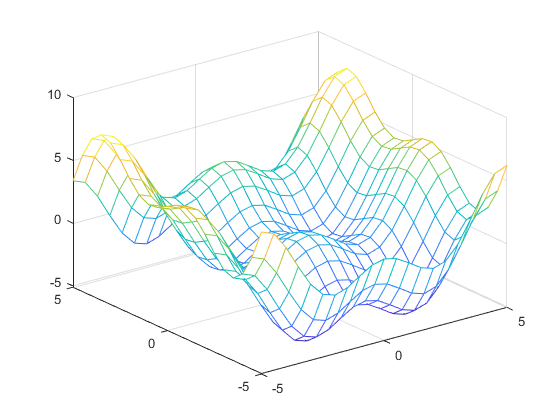

mesh(x,y,z)

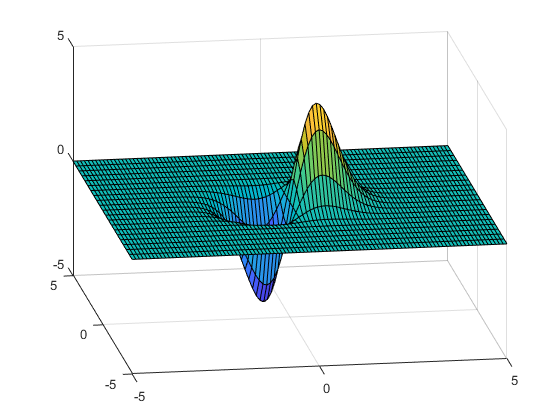

%3
%a
a = 10;
[x,y] = meshgrid(-5:0.1:5, -5:0.5:5);
z = a.*x.*exp(-x.*x - y.*y);
surf(x,y,z)

view([-8.96 23.47])

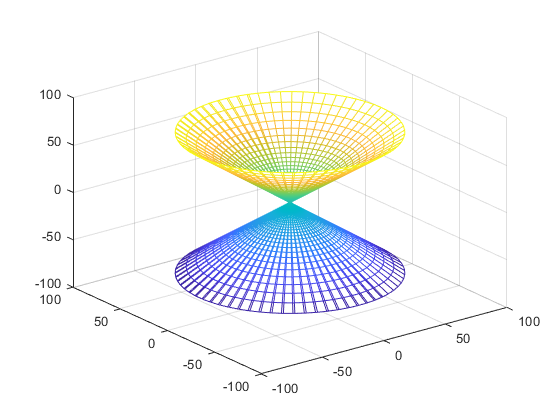

%b
a = 1;
[alpha,beta] = meshgrid(-5:0.1:5, -5:0.1:5);
x = a.*cosh(alpha).*cos(beta);
y = a.*cosh(alpha).*sin(beta);
z = a.*sinh(alpha);
mesh(x,y,z)

%c
r = 1;
p = 4

p = 4

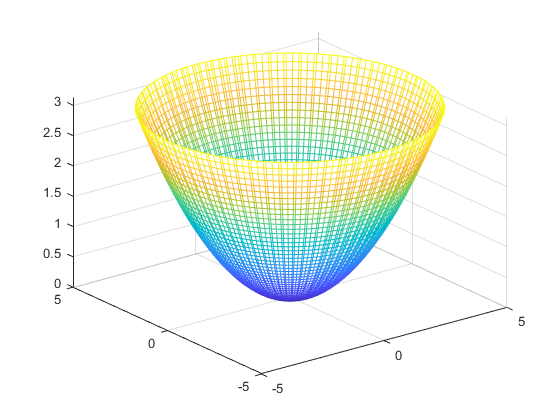

[alpha,beta] = meshgrid(-5:0.1:5, -5:0.1:5);
x = alpha.*cos(beta);
y = alpha.*sin(beta);
z = alpha.^2./(2*p);
mesh(x,y,z)

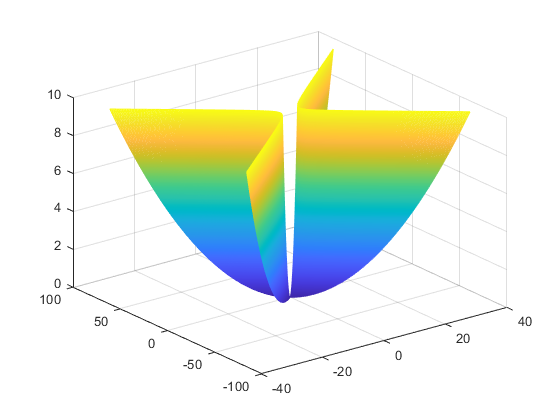

%d
a = 1;
b = 2;
[alpha,beta] = meshgrid(-pi:0.01:pi, -pi:0.01:pi);
x = a .* alpha .* cosh(beta);
y = b .* alpha .* sinh(beta);
z = alpha.^2;
mesh(x,y,z)

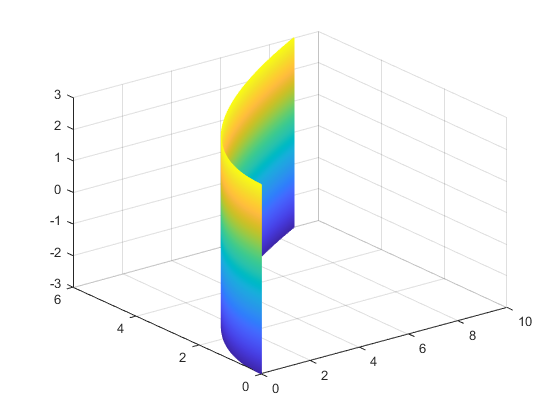

%e
a = 1;
b = 2;
[u,v] = meshgrid(0:0.01:3, -3:0.01:3);
x = a.*u.^2;
y = 2.*a.*u;
z = v;
mesh(x,y,z)

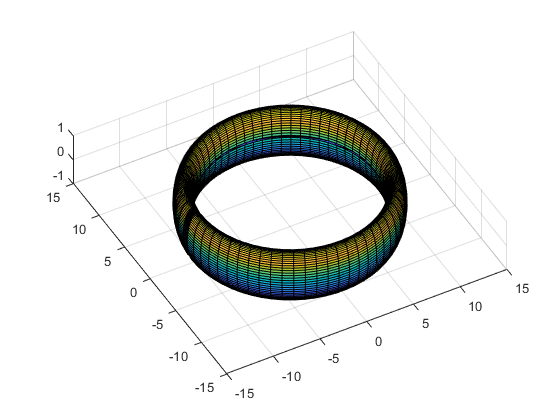

%f Круговой тор
a = 10;
b = 1;
[u, v] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
x = (a + b.*cos(v)).*cos(u);
y = (a + b.*cos(v)).*sin(u);
z = b .* sin(v);
surf(x,y,z)

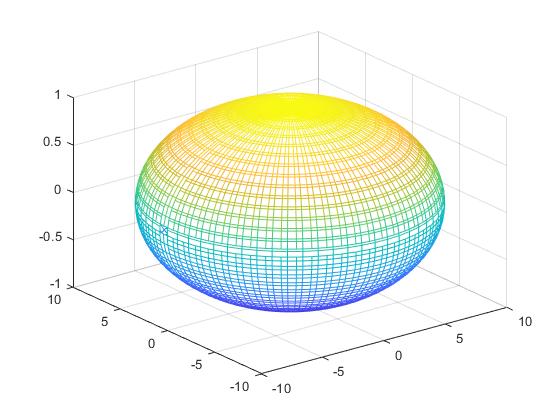

%g Эллипсоид вращения
a = 10;
b = 1;
[u, v] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
x = a.*cos(u).*cos(v);
y = a.*sin(u).*cos(v);
z = b .* sin(v);
mesh(x,y,z)

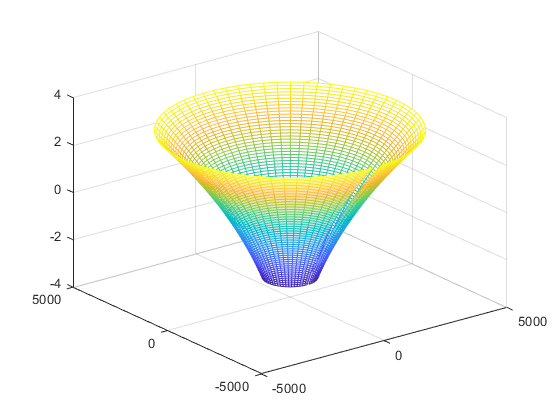

%h Гиперболо-логарифмическая плоскость
a = 10;
b = 10;
[u, v] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
r = a.*(u+b).^2 .* log(u + b);
x = r.*sin(v);
y = r.*cos(v);
z = u;
mesh(x,y,z)

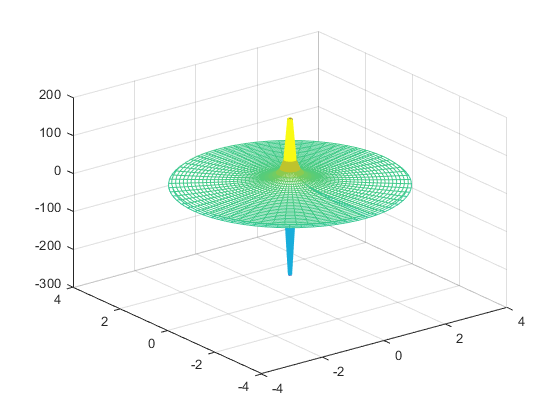

%i Поверхность вращения гиперболы
a = 10;
b = 10;
[u, v] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
x = u.*sin(v);
y = u.*cos(v);
z = b./u;
mesh(x,y,z)

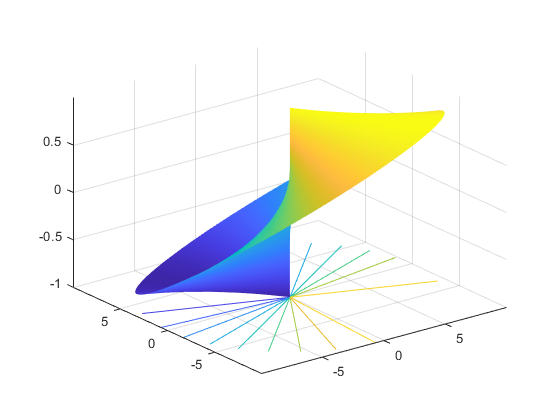

%j Поверхность деформированной сферы
a = 10;
b = 1;
[u, v] = meshgrid(0:0.1:2*pi, -pi/2:0.1:pi/2);
x = a.*cos(u).*cos(v);
y = a.*sin(u).*cos(v);
z = sin(u - a);
surfc(x,y,z)
shading interp

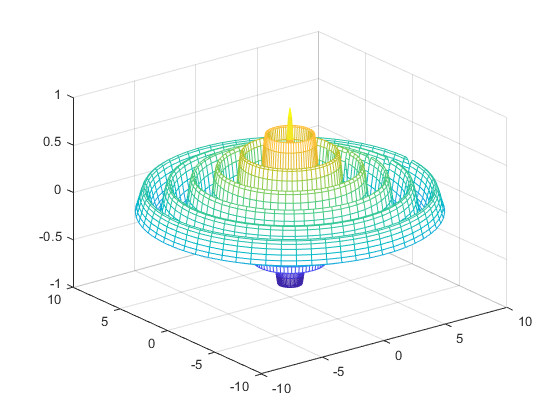

%k Поверхность с затухающими окружными волнами
a = 1;
m = 0.2;
om = 4;
fi = pi/2;
[u, v] = meshgrid(0:0.1:2*pi, 0:0.1:10);
x = v.*cos(u);
y = v.*sin(u);
z = a.*exp(-m.*v).*sin(om.*v + fi);
mesh(x,y,z)

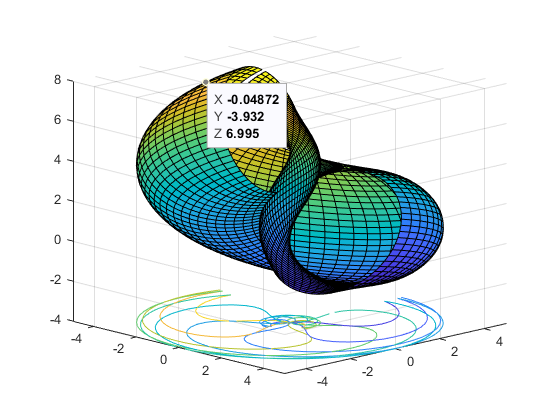

%i Винтовой тор
a = 2;
R = 3;
[u, v] = meshgrid(0:0.1:2*pi, 0:0.1:5);
x = (a + R.*sin(u)).*cos(v);
y = (a + R.*sin(u)).*sin(v);
z = R.*cos(u) + b.*v;
surfc(x,y,z)

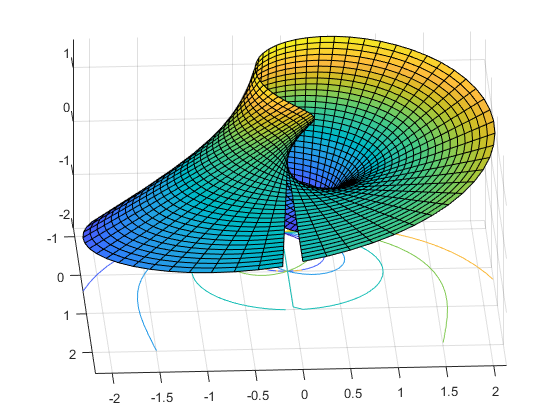

%m Лента Мёбиуса
[u, v] = meshgrid(0:0.1:2*pi, -pi/2:0.1:pi/2);
x = (1 + v.*cos(u./2)).*cos(u);
y = (1 + v.*cos(u./2)).*sin(u);
z = v.*sin(u./2);
surfc(x,y,z)

%4 Построить график функции...
a = pi;
[x, y] = meshgrid(-1:0.01:1, -1:0.01:1);
r = sqrt(x.^2 + y.^2);
f = (2 * besselj(1, a.*r)./r).^2

f =     0.0927    0.0881    0.0836    0.0790    0.0745    0.0700    0.0655    0.0611    0.0567    0.0524    0.0482    0.0441    0.0401    0.0363    0.0325    0.0289    0.0255    0.0223    0.0192    0.0163    0.0137    0.0112    0.0090    0.0070    0.0052    0.0037    0.0024    0.0014    0.0007    0.0002    0.0000    0.0001    0.0005    0.0011    0.0021    0.0033    0.0049    0.0067    0.0088    0.0113    0.0140    0.0169    0.0202    0.0238    0.0276    0.0317    0.0360    0.0406    0.0455    0.0506
    0.0881    0.0835    0.0789    0.0743    0.0698    0.0653    0.0608    0.0564    0.0520    0.0478    0.0437    0.0396    0.0357    0.0320    0.0284    0.0249    0.0217    0.0186    0.0157    0.0131    0.0106    0.0084    0.0064    0.0047    0.0032    0.0020    0.0011    0.0005    0.0001    0.0000    0.0002    0.0007    0.0016    0.0027    0.0041    0.0059    0.0079    0.0103    0.0129    0.0159    0.0191    0.0227    0.0266    0.0307    0.0352    0.0399    0.0449    0.0501    0.0556    0

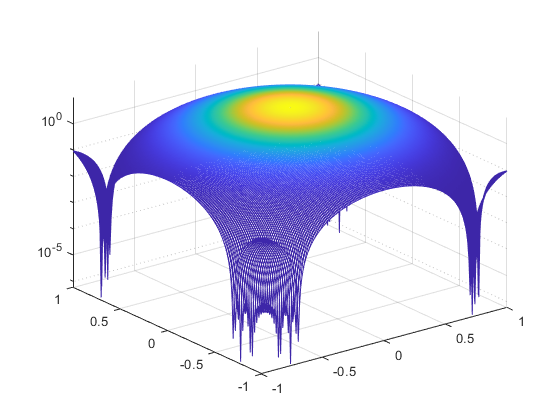

mesh(x,y,f)
set(gca, 'Zscale', 'Log')

%5 Построить поверхность заданную неявным уравнением...
% Я не разобрался с построением функций заданных
% неявными уравнениеми :C